%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                                                         %
%                   LAB 1 - ASEN 2004                     %
%                 Glider Wing Analysis                    %
%                                                         %
%                                                         %
%        This script takes in 2-dimensional data for      %
%            a foam glider and calculates                 %
%        the 3-dimensional whole aircraft drag polar,     %
%        as well as performance analysis calculations     %
%       for maximum glide range, maximum powered range,   %
%             and maximum powered endurance.              %
%                                                         %
%                  Created: 02/03/2021                    %
%               Last Modified: 02/19/2021                 %
%                                                         %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Set Environment

clear
clc
close all

## Declare and Define the Glider Variables

% Given Variables
Re = 160000;                % Glider Reynold's Number [dimensionless]
e0 = 0.601;                 % Glider Oswald's Efficiency 
C_fe = 0.003;              % Civil Transport Skin Friction Coefficient
h = 7;                      % Glider launch altitude [m]
rho = 1.0581;               % Air density STD ATM for Boulder [kg/m^3]
mu = 1.74*(10^-5);          % Viscosity [kg/m s]
W_payload = 1.5696;         % GoPro Camera Weight [N]

% Set User Variables
b = 1;                          % Glider Main Wing Span [m]
w_c_r = 0.071;                  % Glider Main Wing Root Chord [m]
w_c_t = 0.071;                  % Glider Main Wing Tip Chord  [m]
w_lambda = w_c_t/w_c_r;         % Glider Main Wing Taper Ratio [dimensionless]

e_b = 0.25;                     % Glider Elevator Span [m]
e_c_r = 0.05325;                % Glider Elevator Root Chord [m]
e_c_t = 0.026625;               % Glider Elevator Tip Chord  [m]
e_lambda = e_c_t/e_c_r;         % Glider Elevator Taper Ratio [dimensionless]

v_b = 0.1;                      % Glider Vertical Stabilizer Span [m]
v_c_r = 0.071;                  % Glider Vertical Stabilizer Root Chord [m]
v_c_t = 0.05325;                % Glider Vertical Stabilizer Tip Chord  [m]
v_lambda = v_c_t/v_c_r;         % Glider Vertical Stabilizer Taper Ratio [dimensionless]

d = 0.075;                      % Glider Fuselage Width [m]
L = 0.45;                       % Glider Fuselage Length [m]

W_ballast = 0;                  % Glider Ballast Weight [N]

% Define Surface Areas
S_wing = (b/2)*w_c_r*(1+w_lambda);      % Glider Main Wing Planform Area [m^2]
S_ref = S_wing;                         % Glider Reference Planform Area [m^2]
S_vert = (v_b/2)*v_c_r*(1+v_lambda);    % Glider Vertical Planform Area [m^2]
S_elev = (e_b/2)*e_c_r*(1+e_lambda);    % Glider Horizontal Stabilizer Planform Area [m^2]
S_fuselage = (4*L*d);                   % Glider Fuselage Wet Surface Area

% Define Glider Variables
AR = (b^2)/(S_wing);                                        % Glider Aspect Ratio [dimensionless]
S_wet = S_fuselage + (2*S_wing) + (2*S_elev) + (2*S_vert);  % Glider Wet Planform Area [m^2]
W_glider = 0.295*9.81*S_wet;                                % Glider Weight [N]
W = W_glider + W_payload + W_ballast;                       % Total Glider Weight [N]
W_wing = 0.295*9.91*S_ref;                                  % Wing Weight [N]

% Calculate Mean Aerodynamic Chord for main wing
c_bar = (2/3)*w_c_r*((1+w_lambda+(w_lambda^2))/(1+w_lambda));

% Calculate Reynold's Number for Taperd Main Wing
v_flow = 12;   % Velocity of Airflow [m/s] - Currently the max of vel. requirment
reynolds_c_bar = (rho*(v_flow)*c_bar)/mu;

reynolds_crit = 5*(10^5);
x_cr = (reynolds_crit*mu)/(rho*v_flow);
x_c = x_cr/w_c_r;

% Create the Variable Array for the Tempest
vars = [AR, Re, e0, S_wet, S_ref, C_fe, d, b];

% Appendix Two - Flat Plate Approximation Tables
% [AOA C_l C_d C_M]
% dataAct = [-15 -0.6  0.2  0.09;
%          -14 -0.6  0.2  0.09; 
%          -13 -0.7  0.2  0.09;
%          -12 -0.8  0.19 0.085;
%          -11 -0.8  0.18 0.08;
%          -10 -0.75 0.14 0.07;
%          -9  -0.85 0.12 0.055;
%          -8  -0.8  0.1  0.04;
%          -7  -0.7  0.08 0.03;
%          -6  -0.6  0.06 0;
%          -5  -0.5  0.04 -0.01;
%          -4  -0.4  0.02 -0.005;
%          -3  -0.3  0.01 0;
%          -2  -0.2  0.005 0;
%          -1  -0.1  0.005 0;
%          0   0     0     0;
%          1   0.1   0     0;
%          2   0.2   0.005 0;
%          3   0.3   0.01  0;
%          4   0.4   0.02  0;
%          5   0.45  0.04  0;
%          6   0.6   0.06  0;
%          7   0.7   0.08  -0.01;
%          8   0.8   0.12  -0.03;
%          9   0.8   0.13  -0.06;
%          10  0.8   0.14  -0.08;
%          11  0.8   0.16  -0.1;
%          12  0.8   0.18  -0.1;
%          13  0.8   0.19  -0.1;
%          14  0.74  0.21  -0.1;
%          15  0.74  0.22  -0.1;
%          16  0.74  0.24  -0.1;
%          17  0.73  0.25  -0.1;
%          18  0.73  0.26  -0.1;
%          19  0.7   0.28  -0.1;
%          20  0.7   0.3   -0.1;];
     
% S3021 Airfoils at Mach 0.035, RE = 4.5643E04
% [AOA C_l C_d C_M]
dataAct = [ -15.000  -0.5187   0.18707   0.0128; 
            -14.500  -0.5185   0.18925   0.0084;
            -14.000  -0.5300   0.19484   0.0034;
            -13.500  -0.5344   0.19511  -0.0009;
            -13.000  -0.4687   0.16225   0.0022;
            -12.500  -0.4527   0.15573   0.0005;
            -12.000  -0.4489   0.15286  -0.0026;
            -11.500  -0.4711   0.15859  -0.0077;
            -11.000  -0.4483   0.14314  -0.0090;
            -10.500  -0.4077   0.13098  -0.0074;
            -10.000  -0.4053   0.12763  -0.0097;
            -9.500  -0.4418   0.13465  -0.0150;
            -9.000  -0.3821   0.11316  -0.0120;
            -8.500  -0.3740   0.10869  -0.0127;
            -8.000  -0.4303   0.11741  -0.0181;
            -7.500  -0.3507   0.09543  -0.0126;
            -6.500  -0.3402   0.08458  -0.0100;
            -6.000  -0.3707   0.08210  -0.0071;
            -5.500  -0.3476   0.07560  -0.0027;
            -5.000  -0.3530   0.07064   0.0031;
            -4.500  -0.3710   0.06736   0.0111;
            -3.500  -0.3043   0.04040  -0.0337;
            -3.000  -0.2597   0.03705  -0.0325;
            -2.500  -0.2143   0.03184  -0.0321;
            -2.000  -0.1675   0.02894  -0.0309;
            -1.500  -0.1204   0.02678  -0.0294;
            -1.000  -0.0715   0.02231  -0.0280;
            -0.500  -0.0305   0.02244  -0.0269;
             0.000   0.0181   0.02389  -0.0288;
            0.500   0.1078   0.02622  -0.0381;
            1.000   0.1864   0.02819  -0.0450;
            1.500   0.2565   0.03020  -0.0503;
            2.000   0.3281   0.03214  -0.0551;
            2.500   0.3992   0.03417  -0.0595;
            3.000   0.4849   0.03590  -0.0649;
            3.500   0.5330   0.03764  -0.0649;
            4.000   0.5779   0.03956  -0.0641;
            4.500   0.6256   0.04175  -0.0636;
            5.000   0.7033   0.04244  -0.0645;
            5.500   0.7808   0.04209  -0.0635;
            6.000   0.8132   0.04395  -0.0600;
            6.500   0.8423   0.04658  -0.0567;
            7.000   0.8978   0.04656  -0.0528;
            7.500   0.9615   0.04576  -0.0487;
            8.000   1.0696   0.03450  -0.0403;
            8.500   1.1085   0.03758  -0.0372;
            9.000   1.1222   0.03573  -0.0292;
            9.500   1.0951   0.03818  -0.0209;
            10.000   1.0613   0.04523  -0.0147;
            10.500   1.0597   0.05221  -0.0109;
            11.000   1.0846   0.05971  -0.0076;
            11.500   1.0829   0.06792  -0.0063;
            12.000   1.0596   0.07767  -0.0076;
            12.500   1.0237   0.08932  -0.0119;
            13.000   0.9836   0.10353  -0.0195;
            13.500   0.9477   0.11950  -0.0286;
            14.000   0.8871   0.14772  -0.0480;
            14.500   0.8768   0.16156  -0.0548;
            15.000   0.8746   0.17410  -0.0602;
            15.500   0.8811   0.18602  -0.0637;
            16.000   0.8821   0.20903  -0.0733;
            16.500   0.8789   0.21754  -0.0787;
            17.000   0.8926   0.22917  -0.0810;
            17.500   0.9281   0.25205  -0.0808;
            18.000   0.9321   0.26546  -0.0848;
            18.500   0.9147   0.26515  -0.0904;
            19.000   0.9030   0.26726  -0.0962;
            19.500   0.9067   0.27647  -0.0992;
            20.000   0.9132   0.28649  -0.1010;];

## Calculations

% Lateral Directional Stability
% V_v = (V_b*(X_ac_v-X_cg))/(S_ref*b);
X_cg_wing = 0.5*c_bar;
W_fuselage = 0.295*9.81*S_fuselage;
X_cg_fuselage = 0.5*L;
W_vert_stab = 0.295*9.81*S_vert;
X_cg_vert_stab = 0.5*v_b;
W_horz_stab = 0.295*9.81*S_elev;
X_cg_horz_stab = 0.5*e_b;
W_ballast = 0;
X_cg_ballast = 0; % not sure how to calculate this one
X_cg_payload = 0.5*0.039; % dimensions of payload are 0.039x0.0593x0.0698
wing = W_wing*X_cg_wing;
fuselage = W_fuselage*X_cg_fuselage;
vertical_stab = W_vert_stab*X_cg_vert_stab;
horz_stab = W_horz_stab*X_cg_horz_stab;
ballast = W_ballast*X_cg_ballast;
payload = W_payload*X_cg_payload;
X_cg = (fuselage+vertical_stab+horz_stab+ballast+payload)/W;

X_ac_v = 0.25*v_c_t;

V_v = (v_b*(X_ac_v-X_cg))/(S_ref*b)

V_v = -0.0515

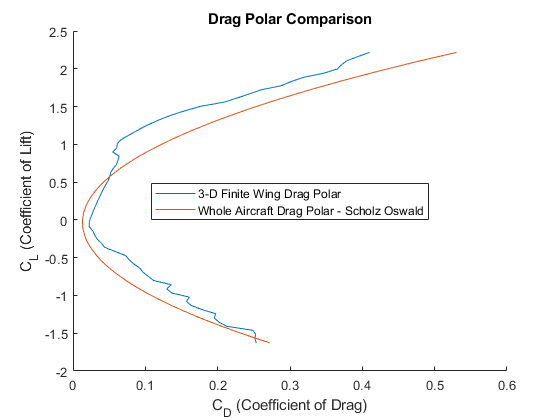


% Calculate the C_L and C_D 
[C_L,C_D_w] = finiteWingLift(dataAct,vars,0,6);

% Calculate the Whole Drag Polar using labDocument method
eLabDocument = labDocument(vars);
[C_D_labDocument,C_D_0_labDocument] = wholeAircraftDragPolar(C_L, C_D_w, eLabDocument, vars);

% Calculate the Whole Drag Polar using MNita_DScholz method
eMNita_DScholz = MNita_DScholz(C_D_w, 0.9, vars);
[C_D_MNita_DScholz,C_D_0_MNita_DScholz] = wholeAircraftDragPolar(C_L, C_D_w, eMNita_DScholz, vars);

% Calculate the Whole Drag Polar using Oberts method
eOberts = oberts(vars);
[C_D_Oberts,C_D_0_Oberts] = wholeAircraftDragPolar(C_L, C_D_w, eOberts, vars);

% Calculate the Whole Drag Polar using Kroo's method
eKroos = kroos(C_D_w, 0.9, vars);
[C_D_Kroos,C_D_0_Kroos] = wholeAircraftDragPolar(C_L, C_D_w, eKroos, vars);

% Combine all Oswald's factors and C_Ds in one array for performance calcs
e0 = [eKroos,eLabDocument,eMNita_DScholz,eOberts];
C_D = [C_D_Kroos,C_D_labDocument,C_D_MNita_DScholz,C_D_Oberts];
C_D_0 = mean([C_D_0_Oberts,C_D_0_labDocument,C_D_0_MNita_DScholz,C_D_0_Kroos]);

% figure;
% hold on
% plot(data(:,1), C_L);
% plot(data(:,1), data(:,2));
% plot(dataAct(:,1), dataAct(:,2),'-.r*');
% title('Lift Curve Comparsion: Tempest UAS');
% xlabel('α (Angle of Attack)');
% ylabel('C_L (Coefficient of Lift)');
% legend('3-D Finite Wing Curve', '2-D Airfoil Curve', 'Tempest CFD Drag Polar', 'Location', 'best');
% hold off

figure;
hold on
%plot(dataAct(:,3), dataAct(:,2));
plot(C_D_w,C_L);
plot(C_D_MNita_DScholz,C_L);
title('Drag Polar Comparison');
ylabel('C_L (Coefficient of Lift)');
xlabel('C_D (Coefficient of Drag)');
legend('3-D Finite Wing Drag Polar','Whole Aircraft Drag Polar - Scholz Oswald','Location','best');
hold off

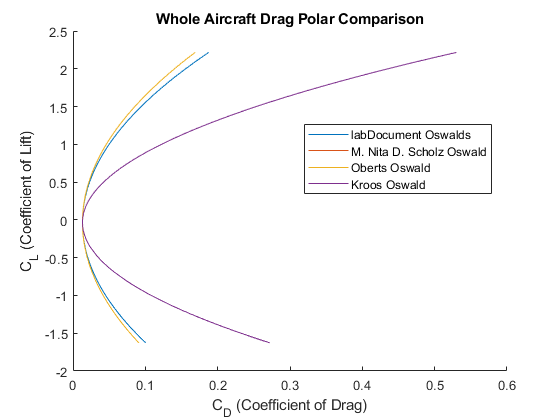


figure;
hold on
plot(C_D_labDocument,C_L);
plot(C_D_MNita_DScholz,C_L);
plot(C_D_Oberts,C_L);
plot(C_D_Kroos,C_L);
%plot(dataAct(:,3),dataAct(:,2));
title('Whole Aircraft Drag Polar Comparison');
xlabel('C_D (Coefficient of Drag)');
ylabel('C_L (Coefficient of Lift)');
legend('labDocument Oswalds', ...
       'M. Nita D. Scholz Oswald', ...
       'Oberts Oswald', ...
       'Kroos Oswald', 'Location', 'best');
%    'Glider CFD Drag Polar'
hold off

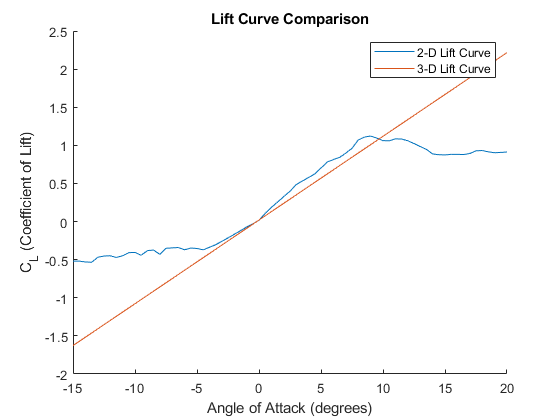


figure;
hold on
plot(dataAct(:,1),dataAct(:,2));
plot(dataAct(:,1),C_L);
title('Lift Curve Comparison');
xlabel('Angle of Attack (degrees)');
ylabel('C_L (Coefficient of Lift)');
legend('2-D Lift Curve','3-D Lift Curve');
hold off

## Performace Flight Conditions Calculations

% Define empty arrays for glide LDmaxes
Glide_LDMax = zeros(1,4);

% Define empty arrays for max glide ranges, endurances, angles and velocities
Glide_Range_V = zeros(1,4);
Glide_Theta = zeros(1,4);
Glide_Range = zeros(1,4);
Glide_Endurance = zeros(1,4);

% performance calculations for each Oswald's using calculated data
for i=1:4
   [Glide_LDMax(i),Glide_Range_V(i),Glide_Theta(i),...
       Glide_Range(i),Glide_Endurance(i)] = ...
       glide(h,C_D(:,i),C_L,e0(i),...
       AR,rho,W,S_ref,C_D_0); 
end

% Tempest performance calculations for avg Oswald's using given data
[FiniteGlide_LDMax,FiniteGlide_Range_V,FiniteGlide_Theta,...
    FiniteGlide_Range,FiniteEndurance] = ...
    glide(h,dataAct(:,3),dataAct(:,2),mean(e0),...
    AR,rho,W,S_ref,C_D_0);

## Print results out to terminal

Results = table([Glide_LDMax';mean(Glide_LDMax);FiniteGlide_LDMax],...
    [Glide_Range_V';mean(Glide_Range_V);FiniteGlide_Range_V],...
    [Glide_Theta';mean(Glide_Theta);FiniteGlide_Theta],...
    [Glide_Range';mean(Glide_Range);FiniteGlide_Range],...
    [Glide_Endurance';mean(Glide_Endurance);FiniteEndurance],...
    'RowNames',{'Kroos','Lab Doc','Scholz','Oberts','Mean','2D'},...
    'VariableNames',{'Glide LDMax','Glide Max Range Velocity (m/s)',...
    'Glide AoA (deg)','Max Glide Range (m)','Glide Endurance (s)'})

Results = 6×5 table
               Glide LDMax    Glide Max Range Velocity (m/s)    Glide AoA (deg)    Max Glide Range (m)    Glide Endurance (s)
               ___________    ______________________________    _______________    ___________________    ___________________

    Kroos        12.432                   13.497                    4.5988               87.024                 8.5129       
    Lab Doc      22.279                     10.3                      2.57               155.95                 19.947       
    Scholz       12.432                   13.497                    4.5988               87.024                 8.5129       
    Oberts       23.646                   10.011                    2.4217               165.52                

## Functions

% finiteWingLift
%
% Function that calculates the 3D finite wing 3D lift coefficient and 3D wing
% drag polar
%
% @param data   The table data that includes the AOA, C_l, and the C_d in
%                   that order.
% @param vars   Needed variables on a per aircraft process like Aspect ratio
%                   and oswald's number
% @param aoa_one The lowest AOA to evaluate at
% @param aoa_two The highest AOA to evaluate at
%

function [C_L,C_D_wing] = finiteWingLift(data,vars,aoa_one,aoa_two)
    % Define the variables
    AR = vars(1);       % Aspect Ratio
    
    % Get the slope of the linear portion of the 2D lift curve from airfoil data
    linearFit = polyfit(data(data(data(:,1)<aoa_two,1)>aoa_one,1),data(data(data(:,1)<aoa_two,1)>aoa_one,2),1);
    
    % Set the slope of 2D airfoil curve as a_0 according to convention
    a_0 = linearFit(1);
    
    % Define the Span Efficiency factor
    e = 0.9;
    
    % Define a the lift curve slope
    a = a_0/(1+((57.3*a_0)/(pi*e*AR)));
    
    % Get the AOA where the C_L equal 0
    alpha_aoa_0 = interp1(data(:,2),data(:,1),0,'linear','extrap'); % FOR ANYTHING ELSE
    %alpha_aoa_0 = data(find(data(:,2)==0),1); % FOR FLAT PLATE
    
    % Calculate C_L for all AOA
    C_L = a*(data(:,1)-alpha_aoa_0);
    
    % Calculate C_D_wing
    C_D_wing = data(:,3) + (C_L.^2)./(pi*e*AR);
end

% wholeAircraftDragPolar
%
% Function that calculates the whole aircraft drag polar
%
% @param C_L        The calculated C_L values for a specific aircraft
% @param C_D_Wing   The calculated C_D_wing values for a specific aircraft
% @param e_0        The Oswald's Efficiency number for a specific model
% @param vars       Needed variables on a per aircraft process like Aspect ratio
%                       and oswald's number
%
function [C_D,C_D_0] = wholeAircraftDragPolar(C_L, C_D_wing, e_0, vars)
    % Define the variables
    AR = vars(1);       % Aspect Ratio
    S_wet = vars(4);    % Wet Planform Area
    S_ref = vars(5);    % Reference Planfrom Area
    C_f_e = vars(6);    % Coefficient of Skin Friction
    
    % Calculate K1
    k_1 = 1/(pi*e_0*AR);
    
    % Calculate C_D_min
    C_D_min = C_f_e * (S_wet/S_ref);
    
    % Calculate C_L_minD
    xmin = find(C_D_wing==min(C_D_wing));
    C_L_minD = C_L(xmin);
    
    % Calculate the Whole Aircraft Drag Polar
    C_D = C_D_min + (k_1*((C_L-C_L_minD).^2));
    
    % Calculate C_D_0
    C_D_0 = C_D_min + (k_1*(C_L_minD^2));
end

## Oswald's Efficiency Calculation Functions

% labDocument
%
% Function that Oswald's number using the Lab Document method equation 12
%
% @param vars       Needed variables on a per aircraft process like Aspect Ratio
%                       and oswald's number
%
function e = labDocument(vars)
    % Define the variables
    AR = vars(1);       % Aspect Ratio
    
    % Calculate Oswald's factor
    e = (1.78*(1-(0.045*(AR^0.68)))) - 0.64;
end

% MNita_DScholz
%
% Function that Oswald's number using M. Nita D. Scholz method
%
% @param C_D        The Coefficient of Drag for Finite Wing
% @param e          The Span Efficieny Factor
% @param vars       Needed variables on a per aircraft process like Aspect ratio
%                       and oswald's number
%
function e = MNita_DScholz(C_D, e, vars)
    % Define the variables
    AR = vars(1);       % Aspect Ratio
    d = vars(7);        % Fuselage Diameter
    b = vars(8);        % Aircraft Wing Span
    K_e_m = 1;          % 1 because aircrafts are subsonic
    
    % Define k_e_f
    k_e_f = 1 - (2*((d/b)^2));
    
    % Find C_D_0
    C_D_0 = C_D(6); % AOA of 0 degrees
    
    % Define Q
    Q = 1 / (e*k_e_f);
    
    % Define P
    P = 0.38*C_D_0;
    
    % Calculate Oswald's factor
    e = K_e_m/(Q+(P*pi*AR));
end

% oberts
%
% Function that Oswald's number using Obert's method
%
% @param vars       Needed variables on a per aircraft process like Aspect ratio
%                       and oswald's number
%
function e = oberts(vars)
    % Define the variables
    AR = vars(1);       % Aspect Ratio

    % Calculate Oswald's factor
    e = 1/(1.05+(0.007*pi*AR));
end

% kroos
%
% Function that Oswald's number using Kroo's method
%
% @param C_D        The Coefficient of Drag for Finite Wing
% @param e          The Span Efficieny Factor
% @param vars       Needed variables on a per aircraft process like Aspect ratio
%                       and oswald's number
%
function e = kroos(C_D, e, vars)
    % Define the variables
    AR = vars(1);       % Aspect Ratio
    d = vars(7);        % Fuselage Diameter
    b = vars(8);        % Aircraft Wing Span
    K = 0.38;           % WTF is K?
    
    % Define u
    u = e;
    
    % Define S
    s = 1 - (2*((d/b)^2));
    
    % Find C_D_0
    C_D_0 = C_D(6); % AOA of 0 degrees
    
    % Define P
    P = K*C_D_0;
    
    % Calculate Oswald's Factor
    e = 1/((1/(u*s))+(P*pi*AR));
end

## Performance Calculations

glide

% Calculates L/Dmax, ranges and velocities for max endurance and max range
% glide

function [LDmax,V_range,theta_range,R_max,endurance] = glide(h,C_D,C_L,e0,AR,rho,W,S,C_D_0)
% max endurance: at 3CD0 = kCL^2
% max range: at CD0 = kCL^2

    % define k
    k = 1/(AR*pi*e0);
    C_L_range = sqrt(C_D_0/k);
    C_L_endur = sqrt(3*C_D_0/k);
    [LDmax,idx] = max(C_L./C_D);
    R_max = h*(C_L(idx)/C_D(idx));
    
    % calculate glide angle
    theta_range = atan(h/R_max);
    
    V_range = sqrt((2*cos(theta_range)*W)/(rho*C_L_range*S));
    V_endur = sqrt((2*cos(theta_range)*W)/(rho*C_L_endur*S));
    sink_rate = V_endur*(sin(theta_range));
    endurance = h/sink_rate;
    theta_range = rad2deg(theta_range);
end